# Text Classification Using Recurrent Neural Networks (RNN)

Óscar Poblete Sáenz

Course: Introduction to Artificial Intelligence

Teacher: Elizabeth Guevara Martinez

clear
clc
% Upload database
filename = "factoryReports.csv";
data = readtable(filename,'TextType','string');
head(data)

ans = 8×5 table
                                 Description                                       Category          Urgency          Resolution         Cost 
    _____________________________________________________________________    ____________________    ________    ____________________    _____

    "Items are occasionally getting stuck in the scanner spools."            "Mechanical Failure"    "Medium"    "Readjust Machine"         45
    "Loud rattling and banging sounds are coming from assembler pistons."    "Mechanical Failure"    "Medium"    "Readjust Machine"         35
    "There are cuts to the power when starting the plant."                   "Electronic Failure"    "High"      "Full Replacement"      16200
    "Fried capacitors in the assembler."                                     "Electronic Failure" 

% Convert labels to classes
data.Category = categorical(data.Category)

data = 480×5 table
                                 Description                                      Category         Urgency          Resolution         Cost 
    _____________________________________________________________________    __________________    ________    ____________________    _____

    "Items are occasionally getting stuck in the scanner spools."            Mechanical Failure    "Medium"    "Readjust Machine"         45
    "Loud rattling and banging sounds are coming from assembler pistons."    Mechanical Failure    "Medium"    "Readjust Machine"         35
    "There are cuts to the power when starting the plant."                   Electronic Failure    "High"      "Full Replacement"      16200
    "Fried capacitors in the assembler."                                     Electronic Failure    "High"

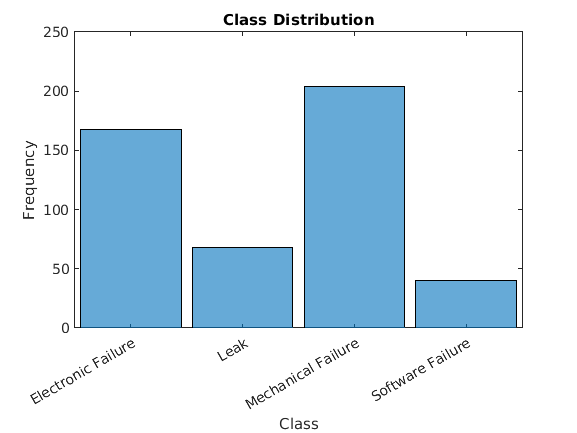

% See class distribution
figure
histogram(data.Category);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

% Divide data into test and training sets
cvp = cvpartition(data.Category,'Holdout',0.2);
dataTrain = data(training(cvp),:);
dataTest= data(test(cvp),:);

% Extract data and labels
textDataTrain = dataTrain.Description;
textDataTest = dataTest.Description;
yTrain = dataTrain.Category;
yTest = dataTest.Category;
textDataTrain(1:5)

ans = 5×1 string array
    "Items are occasionally getting stuck in the scanner spools."
    "Loud rattling and banging sounds are coming from assembler pistons."
    "There are cuts to the power when starting the plant."
    "Fried capacitors in the assembler."
    "Burst pipe in the constructing agent is spraying coolant."


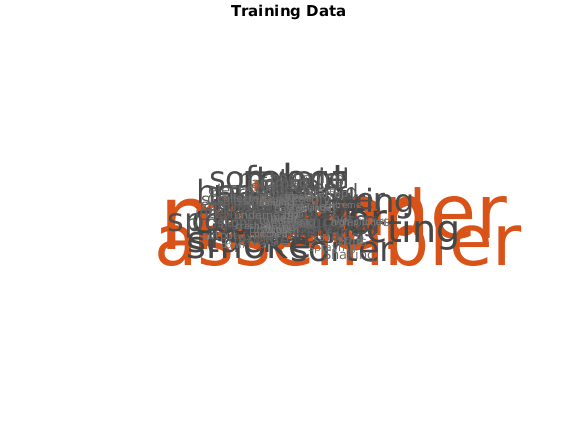

Error using close
Interrupt while evaluating Figure CloseRequestFcn.



% Visualize data
figure
wordcloud(textDataTrain);
title("Training Data")

% Preprocess the data
% Convert to lowercase, remove periods (Regular expressions)
documentsTrain = preprocessText(textDataTrain);
documentsTest = preprocessText(textDataTest);
documentsTrain(1:5)

ans =   5×1 tokenizedDocument:

     9 tokens: items are occasionally getting stuck in the scanner spools
    10 tokens: loud rattling and banging sounds are coming from assembler pistons
    10 tokens: there are cuts to the power when starting the plant
     5 tokens: fried capacitors in the assembler
     9 tokens: burst pipe in the constructing agent is spraying coolant


% Convert to numerical sequence (Embedding)
enc = wordEncoding(documentsTrain);


% Make all vectors the same size
sequenceLength = 10;
XTrain = doc2sequence(enc,documentsTrain,'Length',sequenceLength);
XTrain(1:5)

ans = 5×1 cell array
    {1×10 double}
    {1×10 double}
    {1×10 double}
    {1×10 double}
    {1×10 double}


% Convert test set to number sequences
XTest = doc2sequence(enc,documentsTest,'Length',sequenceLength);

Model

% Define LSTM Model (Long Short Term Memory)
%LSTM has forget and record modules
inputSize = 1;
embeddingDimension = 50;
numHiddenUnits = 80;

numWords = enc.NumWords;
numClasses = numel(categories(yTrain));

layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   6×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 50 dimensions and 438 unique words
     3   ''   LSTM                    LSTM with 80 hidden units
     4   ''   Fully Connected         4 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Classification Output   crossentropyex

% Specify training options
options = trainingOptions('adam', ...
    'MiniBatchSize',16, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false);

% Train network
net = trainNetwork(XTrain,yTrain,layers,options);

Evaluate

reportsNew = [ ...
    "Coolant is pooling underneath sorter."
    "Sorter blows fuses at start up."
    "There are some very loud rattling sounds coming from the assembler."];

documentsNew = preprocessText(reportsNew);

XNew = doc2sequence(enc,documentsNew,'Length',sequenceLength); %Embedding

labelsNew = classify(net,XNew)

labelsNew = 3×1 categorical array
     Leak 
     Electronic Failure 
     Mechanical Failure 


% Evaluation of the test set
preds = classify(net,XTest);

comp=nnz(preds == yTest)

comp = 86

accuracy=comp/numel(preds)

accuracy = 0.8958

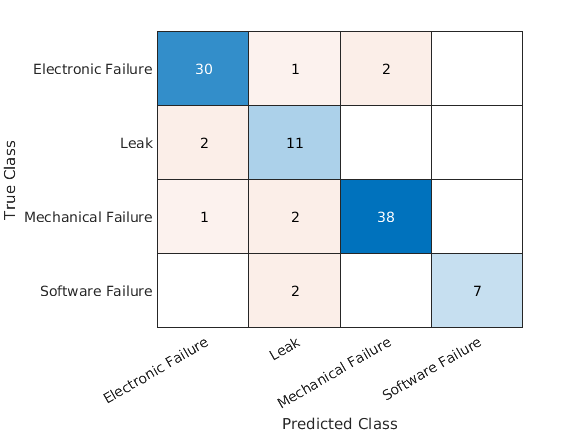

confusionchart(yTest,preds)

function documents = preprocessText(textData)

% Tokenize the text.
documents = tokenizedDocument(textData);

% Convert to lowercase.
documents = lower(documents);

% Erase punctuation.
documents = erasePunctuation(documents);

end